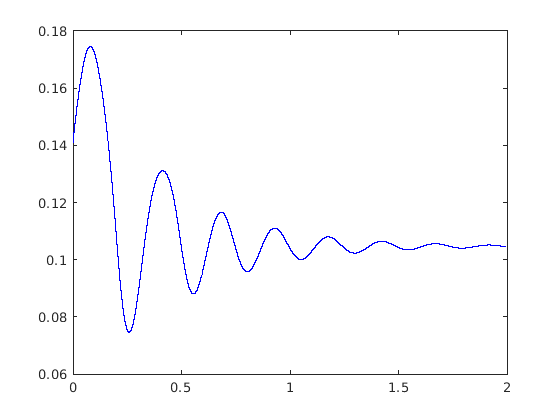

clc; clear all; close all;

m1 = 260; % kg
k1 = 170000; % N/m
L01 = 116/1000; % m
b1 = 13000; % Ns/m^1.5

k2 = 170000; % N/m
L02 = 110/1000; % m
b2 = 9400; % Ns/m^1.5

theta = deg2rad(49); % rad

h0 = 726/1000; % m
h1 = 450/1000; % m

x1 = 141/1000; % m
x1Dot = 745/1000; % m/s

g = 9.81; % m/s^2

simTime = 2; % s
t = 0; % s
dt = 10^-5; % s
idx = 1; % Counter

while(t <= simTime)
    % Calculations
    delta1 = L01-x1;
    delta1Dot = -x1Dot;
    delta2 = x1+h1+L02-h0;
    delta2Dot = x1Dot;

    if(delta1 >0)
    Fk1 = delta1 * k1;
    Fb1 = delta1Dot * b1*sqrt(delta1);
    else
        Fk1 = 0;
        Fb1 = 0;
    end
    if(delta2 > 0)
    Fk2 = delta2 * k2;
    Fb2 = delta2Dot * b2 * sqrt(delta2);
    else
        Fk2 = 0;
        Fb2 = 0;
    end
    Fg1 = m1*g*sin(theta);

    sumF = Fk1+Fb1-Fk2-Fb2-Fg1;
    x1DotDot = sumF/m1;
    % Logging
    t_plt(idx) = t;
    x1_plt(idx) = x1;
    x1Dot_plt(idx) = x1Dot;

    % Time integrate
    x1Dot = x1Dot + x1DotDot*dt;
    x1 = x1 + x1Dot*dt;
    % Update variables
    t = t + dt;
    idx = idx + 1;
end

plot(t_plt, x1_plt, 'b')

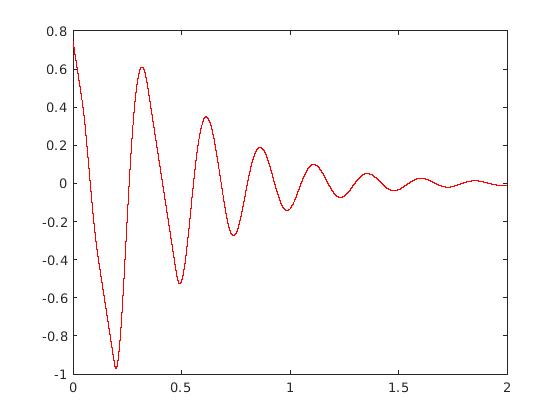

plot(t_plt, x1Dot_plt, 'r')


% What is the maximum absolute value of the velocity [mm/s] of body m1 ?
abs(min(x1Dot_plt))*1000

ans =           969.840424699703
